# **Tutorial 12**: simulating a SDTlib-based model  ( $\approx 2\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

As it was mentionned in the [***introduction***](matlab:open('../Tutorial1/tutorial1.html')) (see tutorial 0), the `SDTlib` is a tool for parametric modelling purpose and not for simulation purpose. Indeed, the SIMULINK model based on the SDTlib blocks reveals algebraic loops which can slow down the simulation run time.

Nevertheless, it shown in this tutorial how it is possible to simulate such a model using a new SIMULINK file where the model of the mechanical system $\mathbf M(\mathrm s,\mathbf\Delta,\theta)$is implemented using a `Linear Parameter Varying (LPV)` Model (from the sub-libray `Control system Tooolbox>Linear Parameter Varying`).

Indeed, once the model $\mathbf M(\mathrm s,\mathbf\Delta,\theta)$is computed (for instance using the function `ulinearize`), the algebraic loops are solved once for all. Then for the simulation, one can freeze the value of the uncertain parameters (for instance $\mathbf\Delta$) and use the known varying parameters (for instance the geometric configuration $\theta$) as scheduling variables. That is what it is done by the block `LPV model with input parameters` whose dialog bock and description is given in the following Figure.

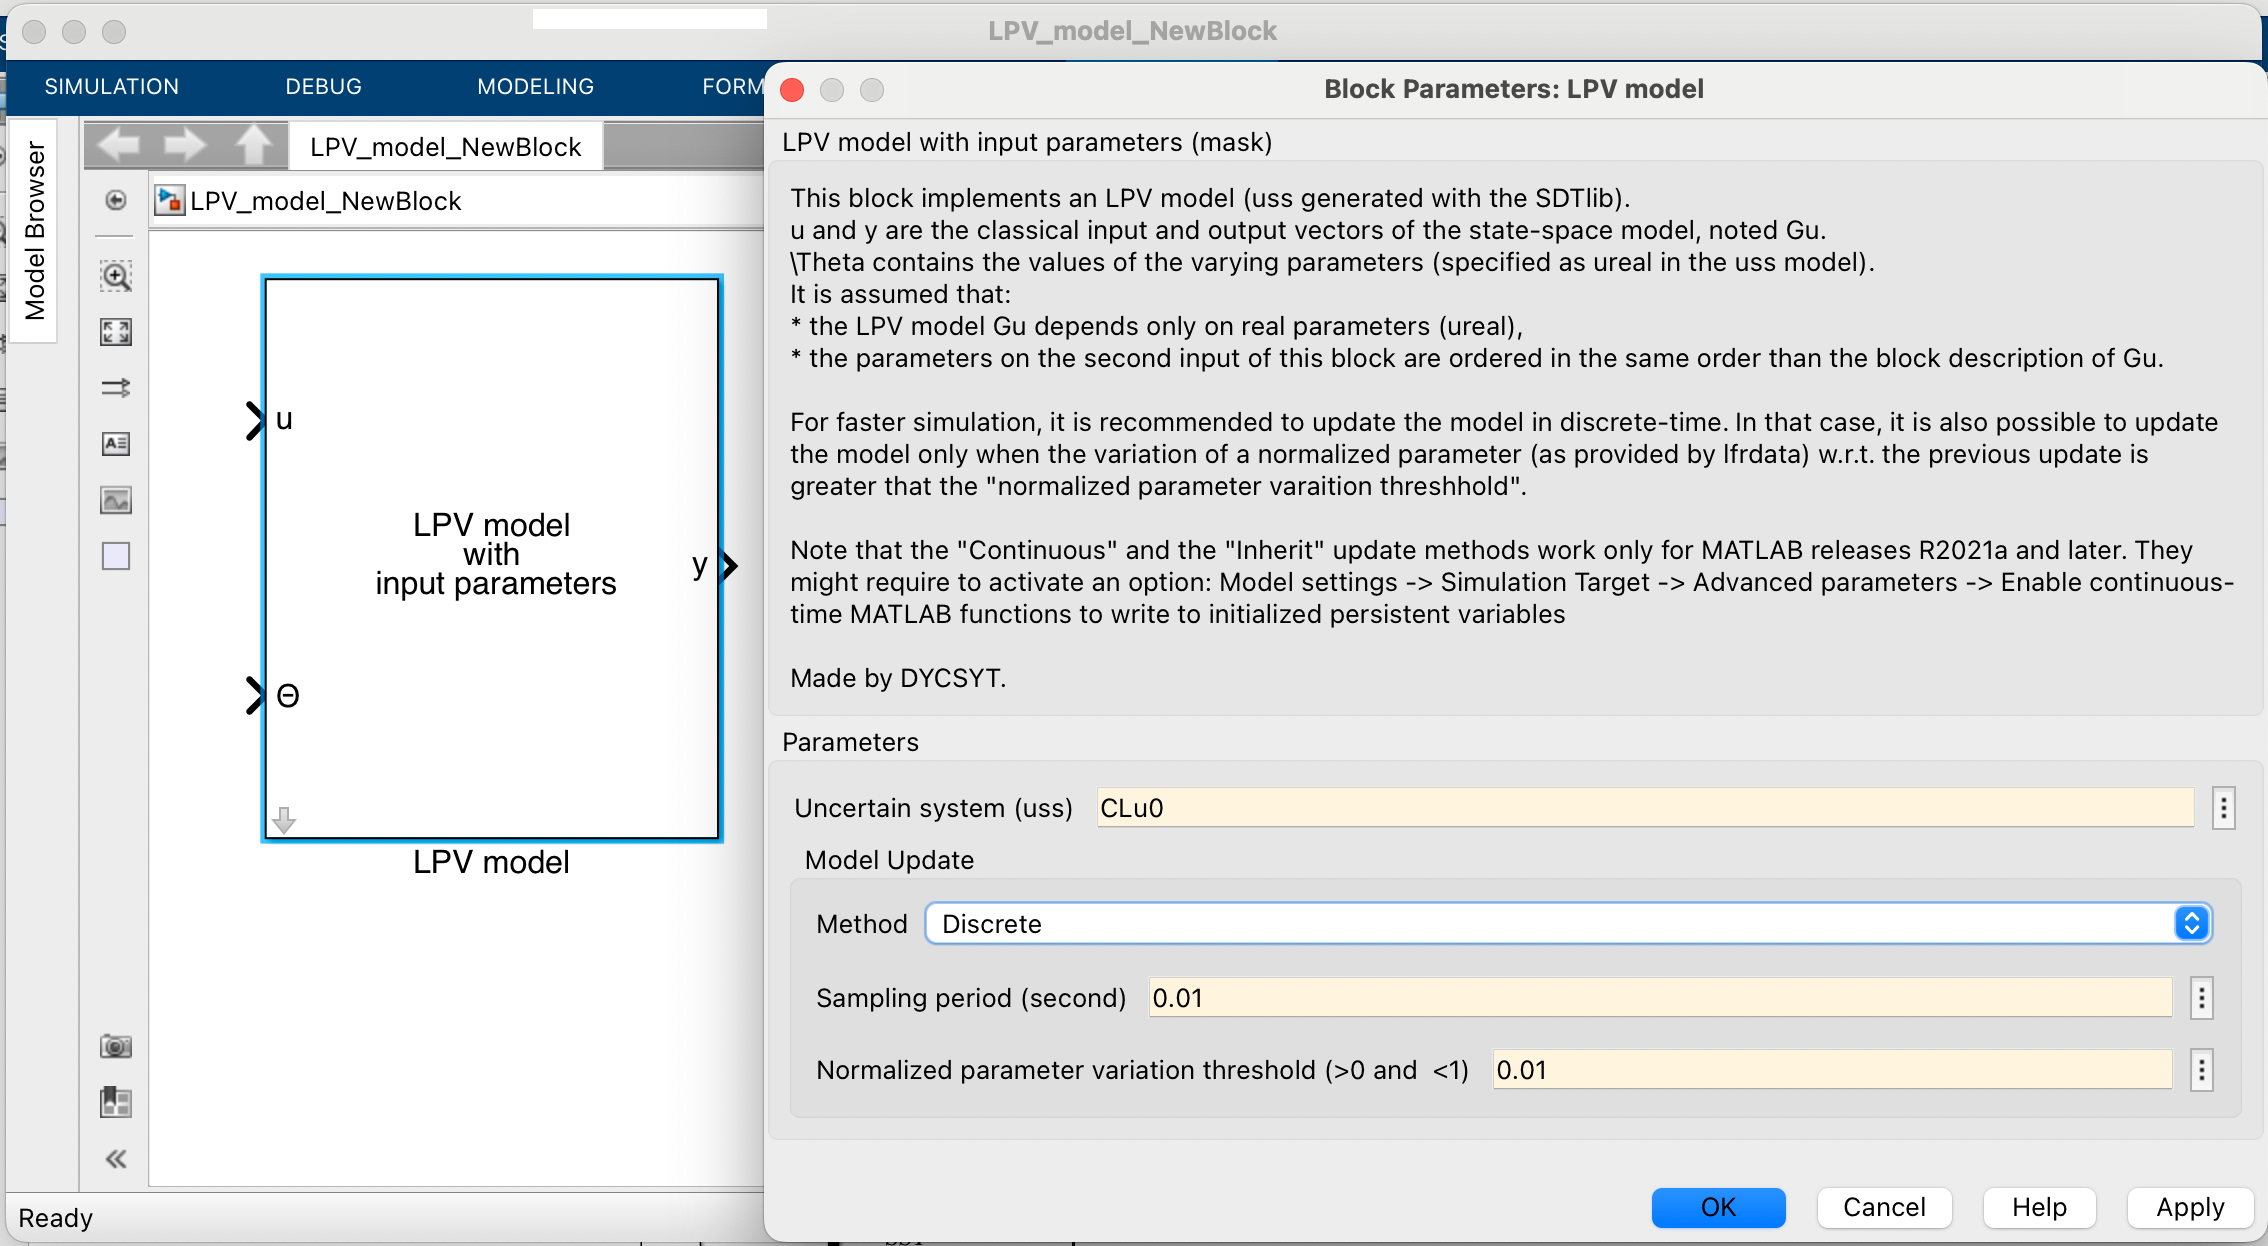

The following illustration reconsiders the closed-loop model designed in the tutorial 3 [***Robust attitude control design of a spacecraft with 2 symmetrical rotating solar arrays***](matlab:open('../Tutorial3/tutorial3.html')) and saved in the file `OptimalDesign.mat`. A whole orbit is simulated and it is assumed that the geometrical configuration $\theta$ of the solar arrays varies from $-\pi$ to $+\pi$ during this orbit. The system is submitted to orbital disturbances, internal SADM disturbances, star sensor and gyrometer noises.

## 2. From the `uss` model to `LPV` model

Let us load the optimal closed-loop model $\mathbf P(\mathrm s,\mathbf\Delta,\theta,\widehat \mathbf K)$ (`CLu`) previoulsy obtained:

load OptimalDesign
CLu

CLu =

  Uncertain continuous-time state-space model with 6 outputs, 11 inputs, 43 states.
  The model uncertainty consists of the following blocks:
    IBx: Uncertain real, nominal = 75, variability = [-20,20]%, 1 occurrences
    IBy: Uncertain real, nominal = 40, variability = [-20,20]%, 1 occurrences
    IBz: Uncertain real, nominal = 80, variability = [-20,20]%, 1 occurrences
    mB: Uncertain real, nominal = 1e+03, variability = [-20,20]%, 3 occurrences
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences
    w1: Uncertain real, nominal = 5.6, variability = [-20,20]%, 4 occurrences
    w2: Uncertain real, nominal = 19.3, variability = [-20,20]%, 4 occurrences
    w3: Uncertain real, nominal = 35.4, variability = [-20,20]%, 4 occurrences

Type "CLu.NominalValue" to see the nominal value, "get(CLu)" to see all properties, and "CLu.Uncertainty" to interact with the uncertain elements.



Let us consider the nominal value of the uncertain parameters ($\mathbf\Delta$):

CLu0=usubs(CLu,'IBx',75,'IBy',40,'IBz',80,'mB',1000,'w1',5.6,'w2',19.3,'w3',35.4)

CLu0 =

  Uncertain continuous-time state-space model with 6 outputs, 11 inputs, 43 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences

Type "CLu0.NominalValue" to see the nominal value, "get(CLu0)" to see all properties, and "CLu0.Uncertainty" to interact with the uncertain elements.



## 3. The simulation model

The simulation model `SimulationModel.slx` is depicted in the follwong Figure:

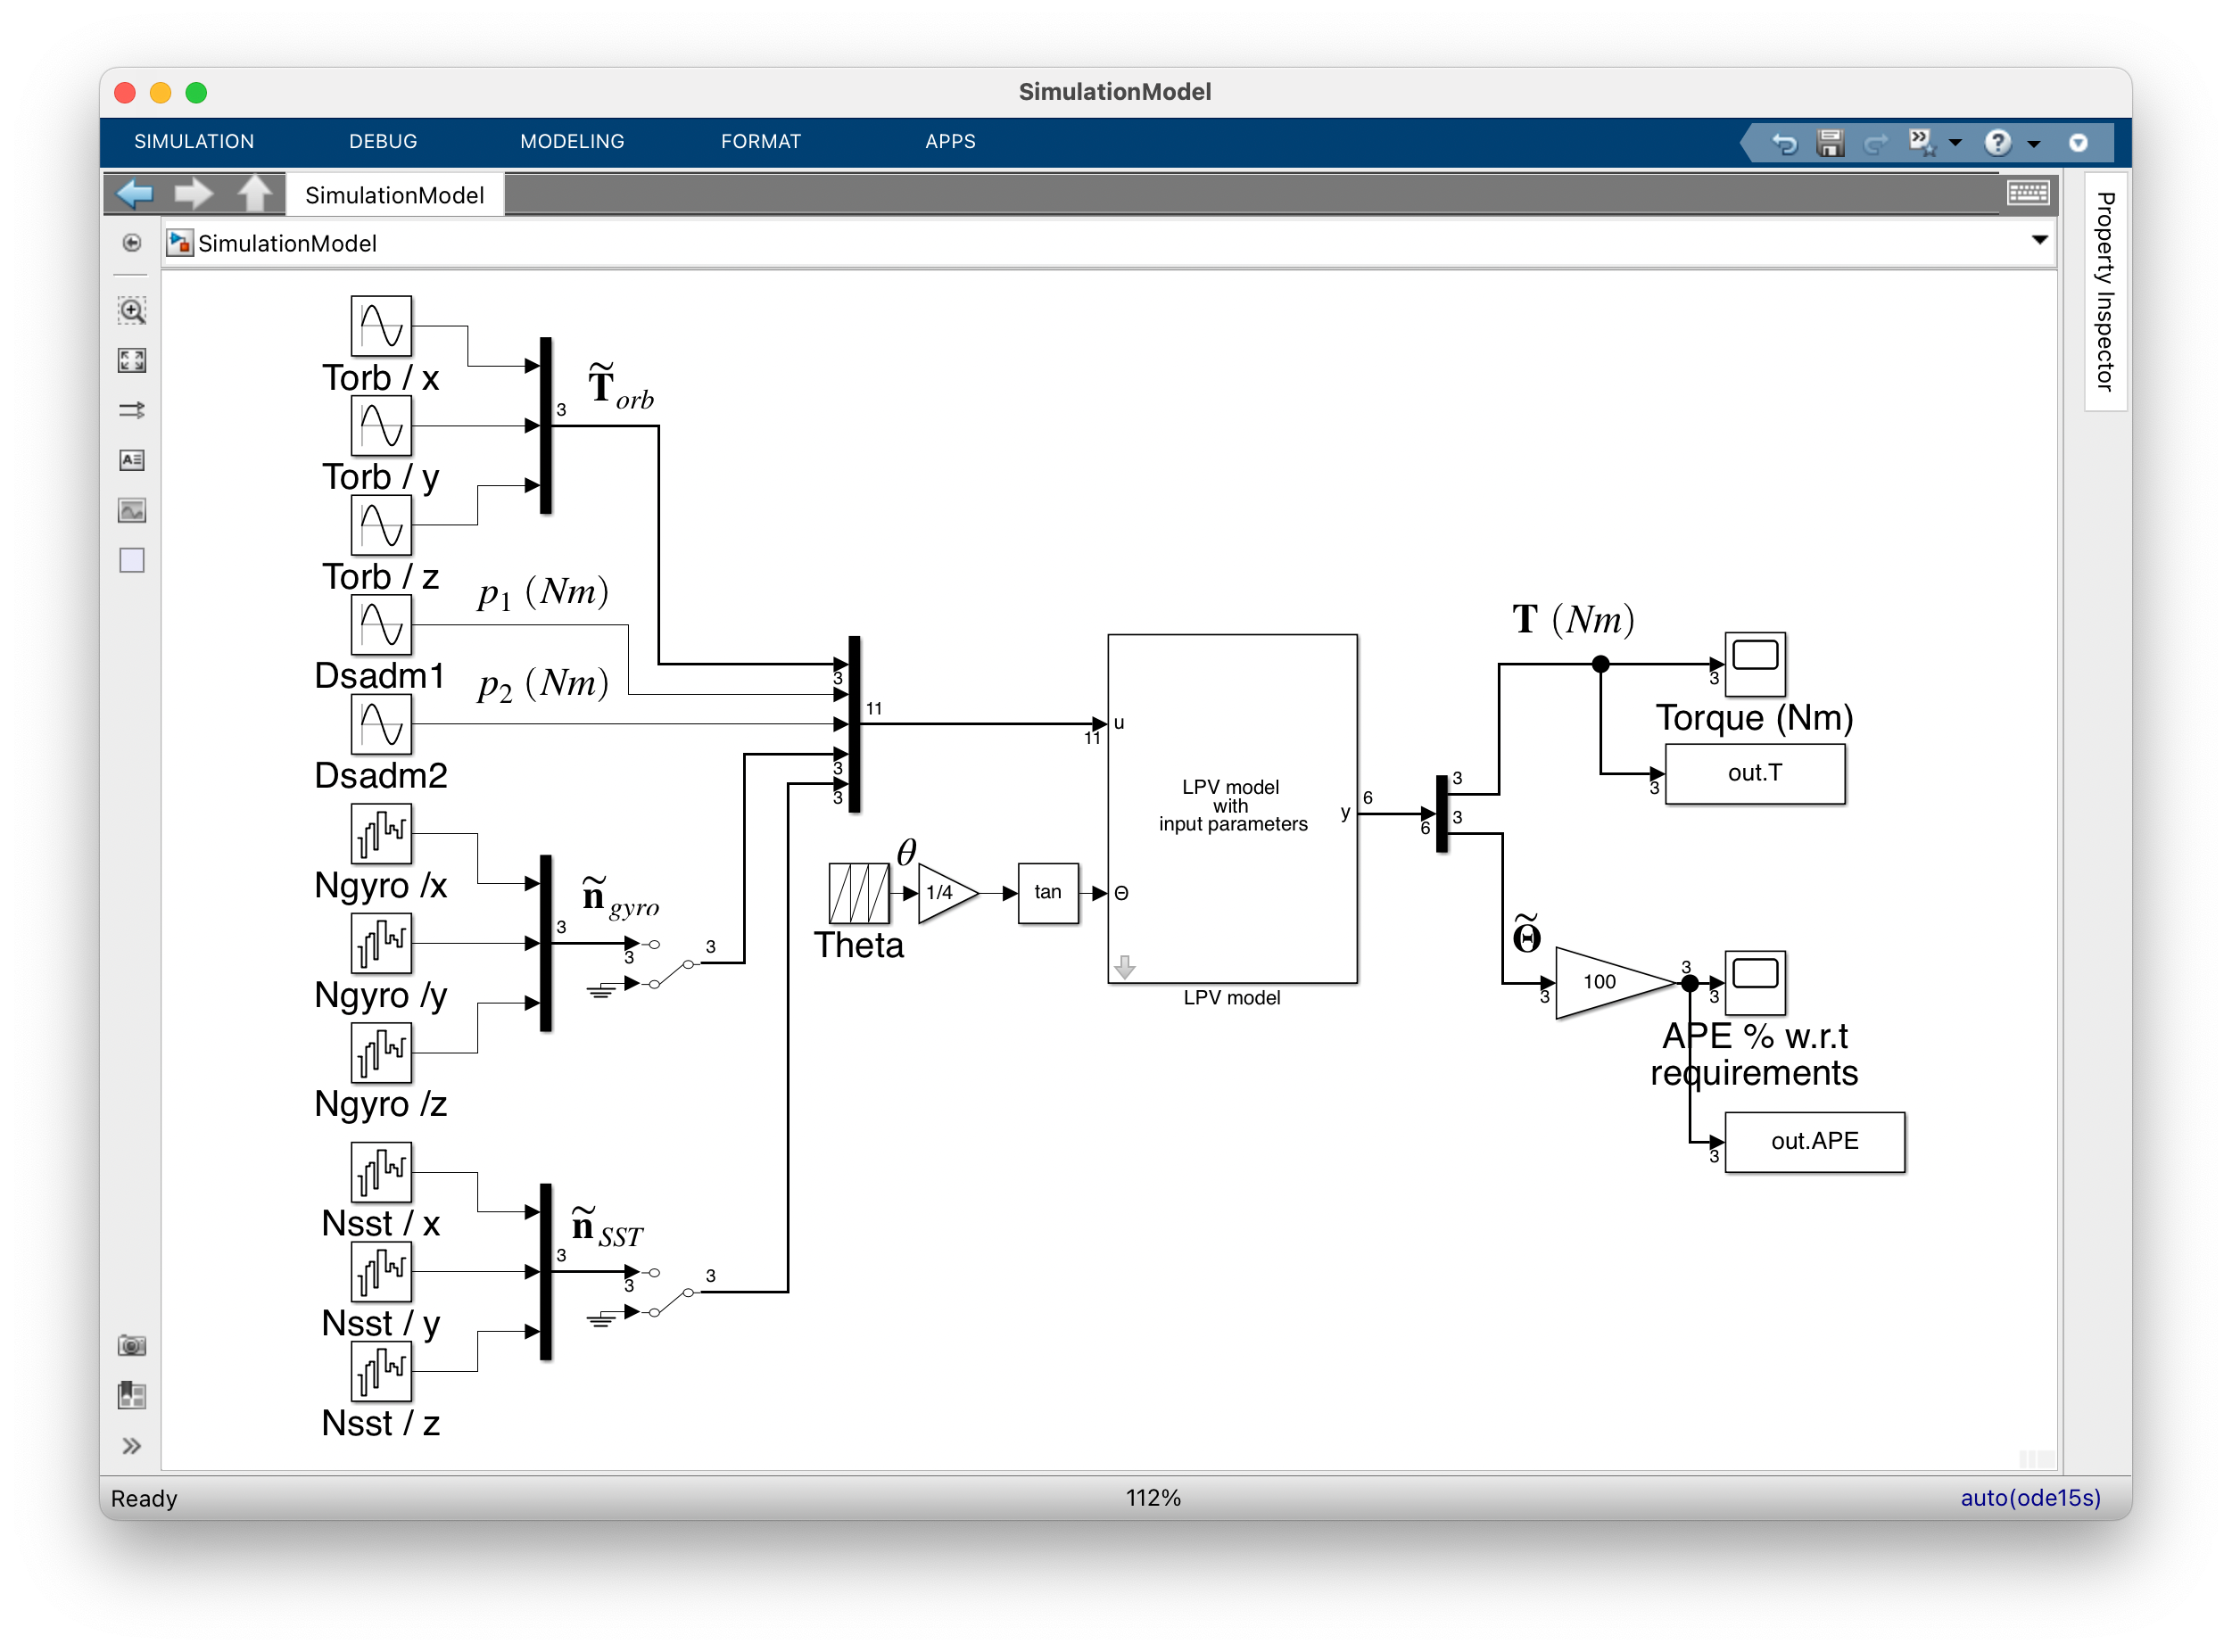

The input signals are:

- normalized orbital disturbances ( $\tilde\mathbf T_{orb$) at the orbital frequency,

- harmonic internal disturbances on the 2 SADM ( $p_1$ and $p_2$ ) : magnitude $0.1\;(Nm)$, frequency $21.4\;(rd/s)$,

- the normalised noises on the star tracker ( $\tilde\mathbf n_{SST}$ ) and the gyrometer  ( $\tilde\mathbf n_{gyro}$ ) are not taken into account (switch off) since they slow down the simulation over one orbit. 

The simulation run time is around $5\;mn$ to simulate the whole orbit ( $5000\,s$). The responses of the $2$ outputs:

- the torque applied to the spacecraft by the reaction wheel system $\mathbf T\;(Nm)$,

- the normalized pointing error $\tilde\mathbf\Theta$

can then be plotted and analyzed:

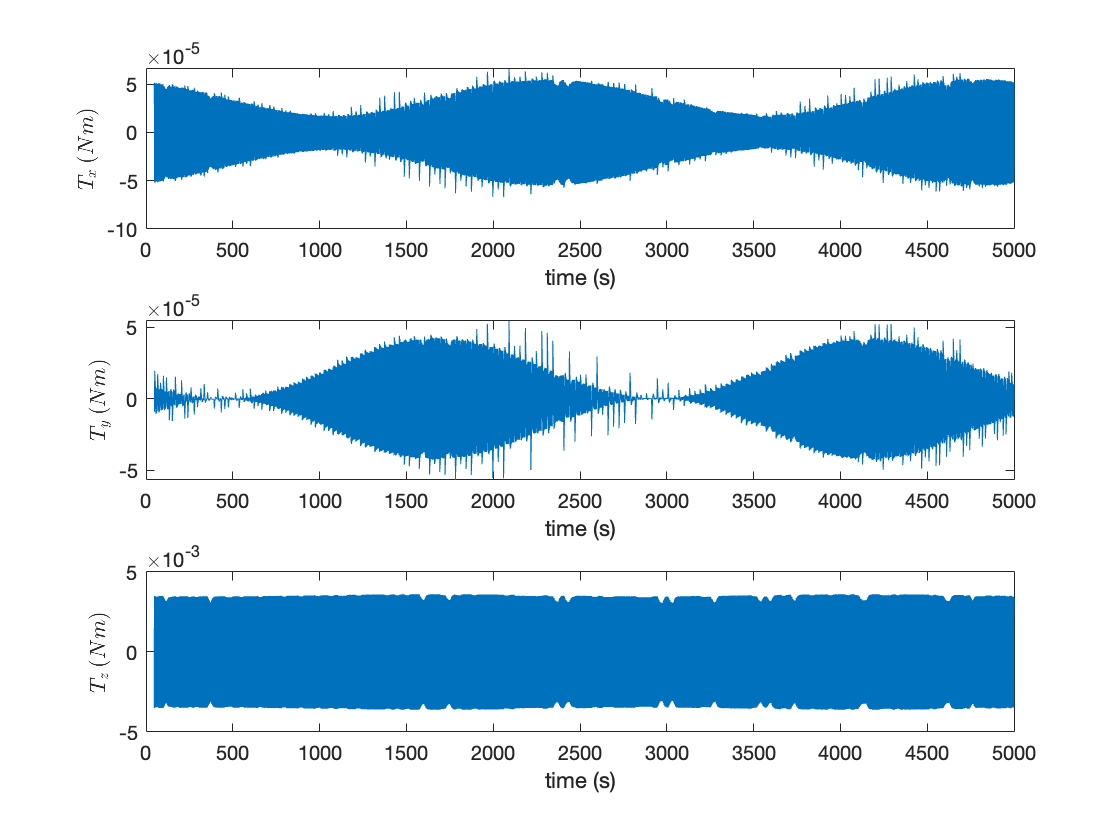

% Simulation Orbital period
T=5000; % (s)

SimulationModel
Simout=sim('SimulationModel');
% Plot the results (with out transcient response)
figure
subplot(3,1,1)
plot(Simout.tout(10000:end),Simout.T.signals.values(10000:end,1))
xlabel('time (s)');
ylabel('$T_x\,(Nm)$','Interpreter','latex')
subplot(3,1,2);
plot(Simout.tout(10000:end),Simout.T.signals.values(10000:end,2))
xlabel('time (s)');
ylabel('$T_y\,(Nm)$','Interpreter','latex')
subplot(3,1,3);
plot(Simout.tout(10000:end),Simout.T.signals.values(10000:end,3))
xlabel('time (s)');
ylabel('$T_z\,(Nm)$','Interpreter','latex')

One can check the resonance due to the SADM disturbances and the exchange between $\mathbf x$ and $\mathbf y$ axes according to the solar array angular configuration $\theta$.

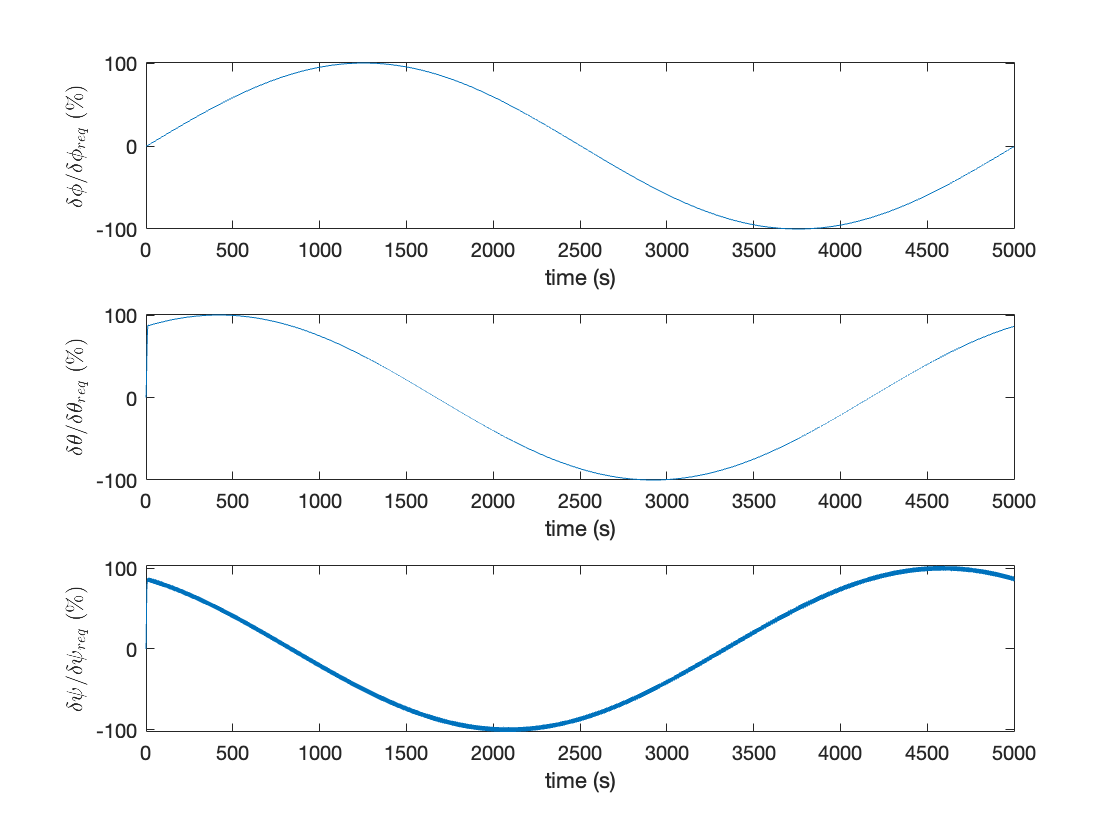

figure
subplot(3,1,1)
plot(Simout.tout,Simout.APE.signals.values(:,1))
xlabel('time (s)');
ylabel('$\delta\phi/\delta\phi_{req}\;(\%)$','Interpreter','latex')
subplot(3,1,2);
plot(Simout.tout,Simout.APE.signals.values(:,2))
xlabel('time (s)');
ylabel('$\delta\theta/\delta\theta_{req}\;(\%)$','Interpreter','latex')
subplot(3,1,3);
plot(Simout.tout,Simout.APE.signals.values(:,3))
xlabel('time (s)');
ylabel('$\delta\psi/\delta\psi_{req}\;(\%)$','Interpreter','latex')

The error is always between $\pm100\%$ of the requirement.